测试不同的参数化方法对于样条插值的效果。

addpath(genpath('../funcs'));

clc

load ../output_data/tool/toolTheo20220817T153907.mat toolFit;
% toolFit (2,n) is the points that need to fit.

k = 3; % degree of the B-spline
u = 0:0.0002:1;
nPts = length(u);


## 常见的参数化方法

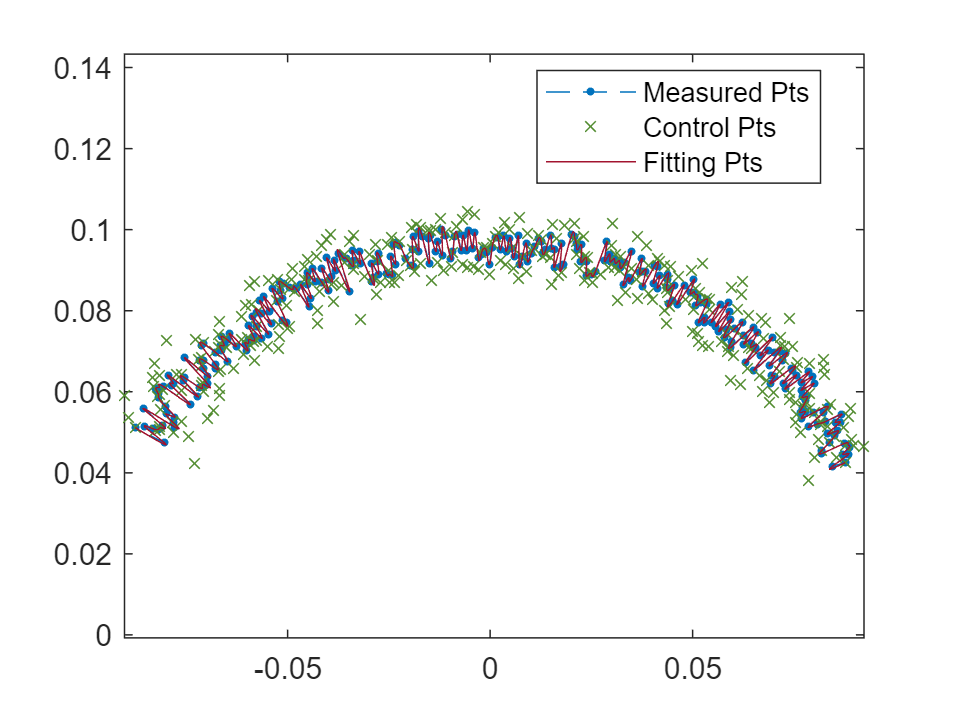

% 均匀参数化
[toolPtUniform,toolCptsUniform] = bsplinePts_spapi(toolFit,k,u,'interpMethod','uniform');
figure('Name','Tool Interpolation Results (uniform parameterization)');
plot(toolFit(1,:),toolFit(2,:),'--.', ...
    'MarkerSize',8,'Color',[0,0.447,0.741]); hold on;
plot(toolCptsUniform(1,:),toolCptsUniform(2,:),'x','Color',[0.32,0.55,0.19],'MarkerSize',5);
plot(toolPtUniform(1,:),toolPtUniform(2,:),'Color',[0.635,0.078,0.184]);
axis equal
legend('Measured Pts','Control Pts','Fitting Pts','Location','best');

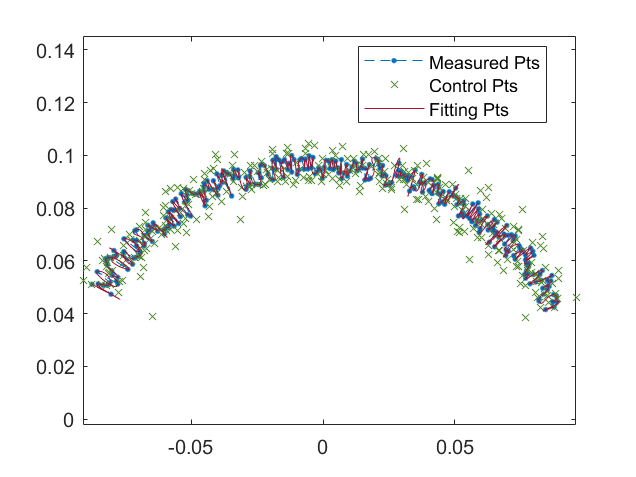


% 弦长参数化
[toolPtChord,toolCptsChord] = bsplinePts_spapi(toolFit,k,u,'interpMethod','chord');
figure('Name','Tool Interpolation Results (chord parameterization)');
plot(toolFit(1,:),toolFit(2,:),'--.', ...
    'MarkerSize',8,'Color',[0,0.447,0.741]); hold on;
plot(toolCptsChord(1,:),toolCptsChord(2,:),'x','Color',[0.32,0.55,0.19],'MarkerSize',5);
plot(toolPtChord(1,:),toolPtChord(2,:),'Color',[0.635,0.078,0.184]);
axis equal
legend('Measured Pts','Control Pts','Fitting Pts','Location','best');

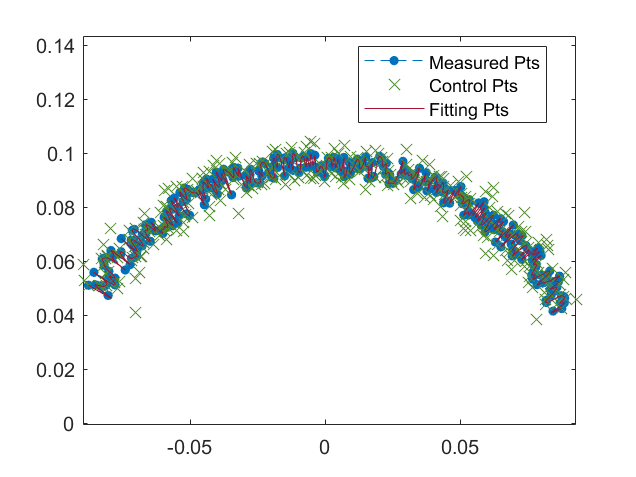


% 向心参数化
[toolPtConcen,toolCptsConcen] = bsplinePts_spapi(toolFit,k,u,'interpMethod','concentric');
figure('Name','Tool Interpolation Results (concentric parameterization)');
plot(toolFit(1,:),toolFit(2,:),'--.', ...
    'MarkerSize',16,'Color',[0,0.447,0.741]); hold on;
plot(toolCptsConcen(1,:),toolCptsConcen(2,:),'x','Color',[0.32,0.55,0.19],'MarkerSize',8);
plot(toolPtConcen(1,:),toolPtConcen(2,:),'Color',[0.635,0.078,0.184]);
axis equal
legend('Measured Pts','Control Pts','Fitting Pts','Location','best');

## 最新参数化方法

## 画图比较

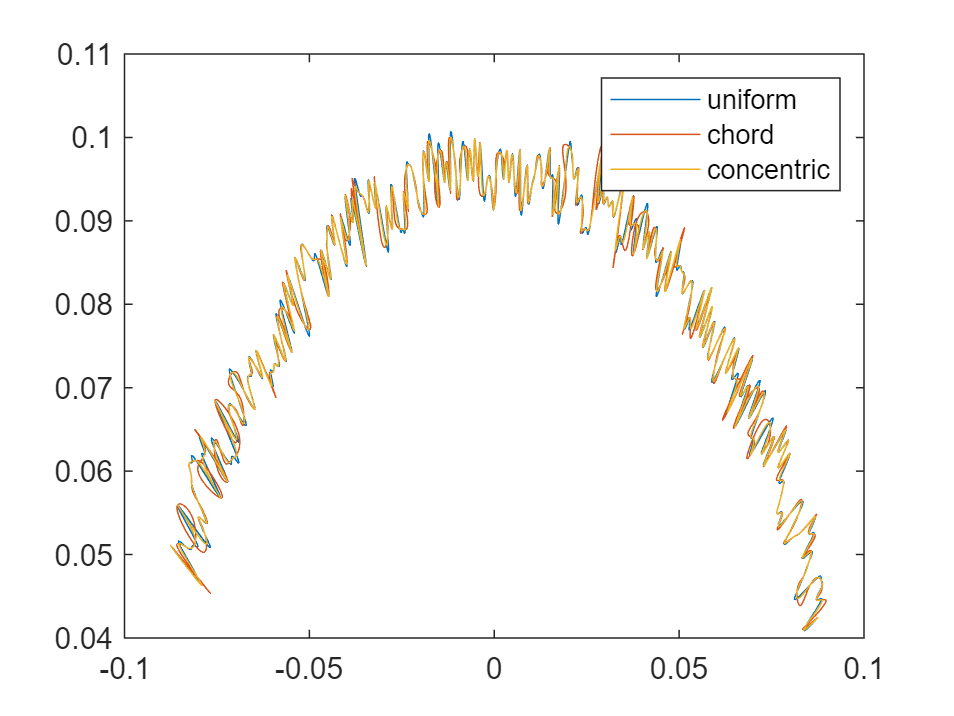

figure;
colorMat = get(gca,'ColorOrder');
plot(toolPtUniform(1,:),toolPtUniform(2,:),'Color',colorMat(1,:)); hold on;
plot(toolPtChord(1,:),toolPtChord(2,:),'Color',colorMat(2,:));
plot(toolPtConcen(1,:),toolPtConcen(2,:),'Color',colorMat(3,:));

legend('uniform','chord','concentric');